set = 'Mel_high';
m = measurements(set);

avgMeasurements = [];
for measurement = m
    avgMeasurements = [avgMeasurements averageMeasurements(measurement)];
end

receptorContrasts = measurementsToReceptorContrasts(avgMeasurements,receptors);

% Select only the contrasts with the background
backgroundIdx = ceil(length(receptorContrasts)/2);
receptorContrasts = receptorContrasts(backgroundIdx,:,:);
receptorContrasts = reshape(permute(receptorContrasts,[3 1 2]),4,[]);

% LMS contrast
LMS = sum(receptorContrasts(1:3,:),1)/3;
LminusM = receptorContrasts(1,:)-receptorContrasts(2,:);

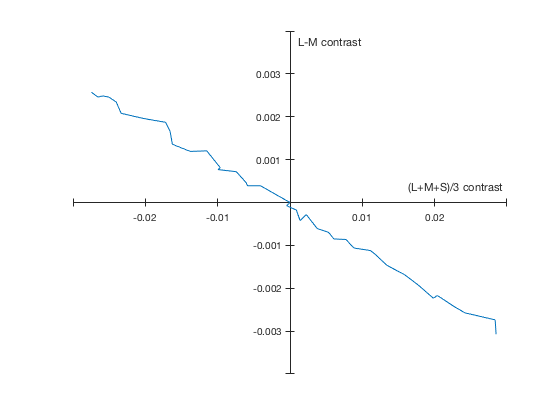

plotPostreceptoralContrasts(LMS,LminusM)